# **Circuitos Electricos II**

**Roberto Sanchez Figueroa    **

**brrsanchezfi@unal.edu.co**

# **Soluciones propuestas para los ejercicios del taller 8**

## Problema 1

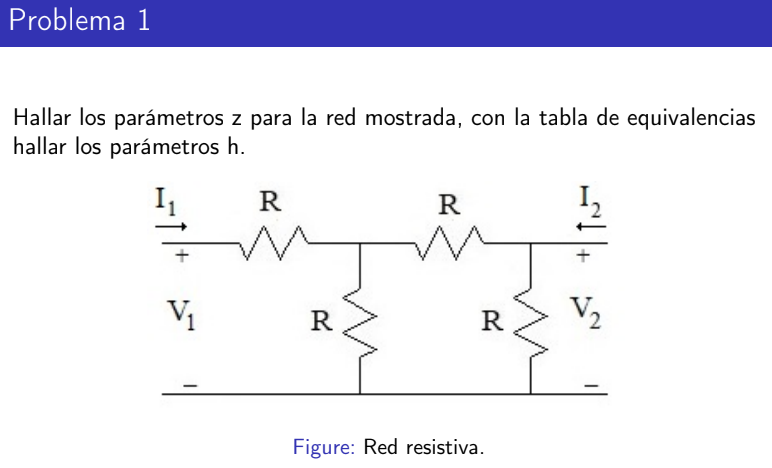

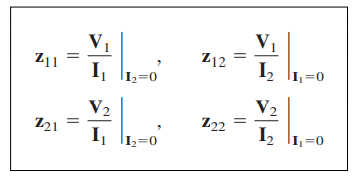

syms z_11 z_12 z_21 z_22...
     V_1 V_2...
     I_1 I_2...
     R

### Cálculo parámetro z

Para cada puerto conectamos una fuente de corriente

z_11

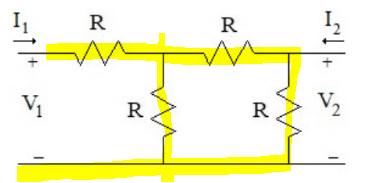

z_11 = R + paralelo(R,R+R)

$$z\_11 = 1.6667\,R$$

z_21

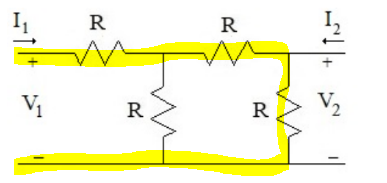

Divisor de corriente y caida de tension en R

z_21 = (R/(R+2*R))*R

$$z\_21 = 0.3333\,R$$

z_22

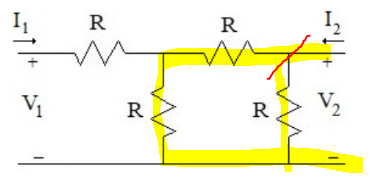

z_22 = paralelo(R,R+R)

$$z\_22 = 0.6667\,R$$

z_12 

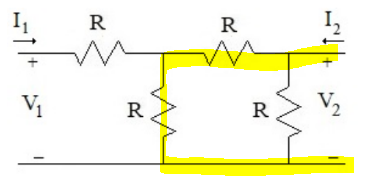

z_12 = (R/(R+2*R))*R

$$z\_12 = 0.3333\,R$$

### Cálculo parámetro h

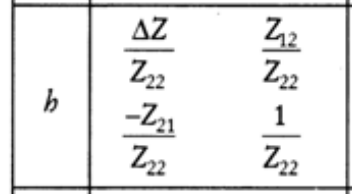

Delta z

D_z = z_11*z_22-z_12*z_21

$$D\_z = R^{2}$$


h = [D_z/z_22 z_12/z_22;
     -z_21/z_22 1/z_22]

$$h = \left(\begin{array}{cc} 1.5000\,R & 0.5000\\ -0.5000 & \frac{1.5000}{R} \end{array}\right)$$

## Problema 2

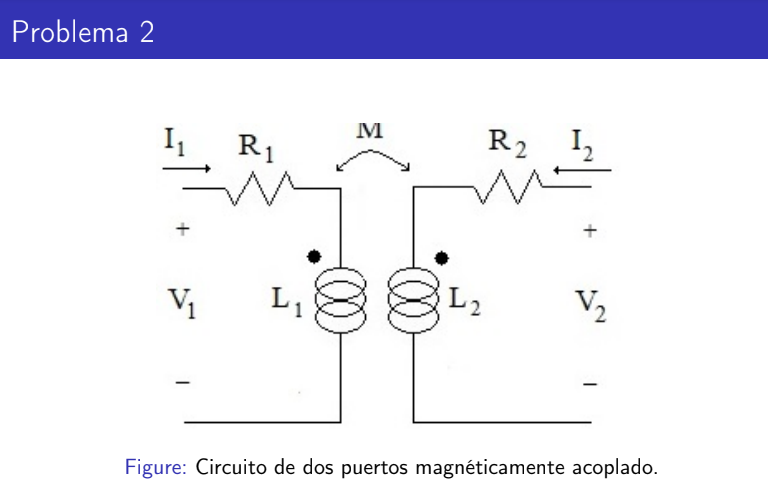

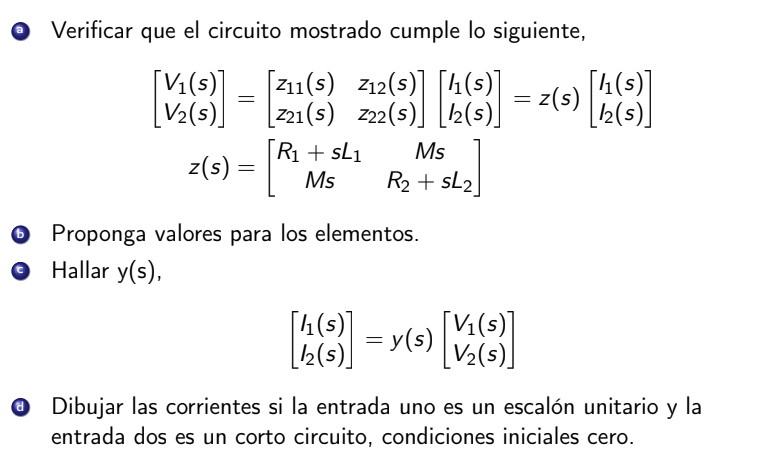

### A) Parametro z

syms R1 R2 L1 L2 M s
z=[R1+s*L1 s*M;
   s*M (s*L2+R2)]

$$z = \left(\begin{array}{cc} R_{1}+L_{1}\,s & M\,s\\ M\,s & R_{2}+L_{2}\,s \end{array}\right)$$

### B) Asignacion de valores

R_1 = 1;
R_2 = 1;
L_1 = 1;
L_2 = 1;
k = 0.5;
M_1 = sqrt(L_1*L_2)*k

M_1 = 0.5000

z = subs(z,[R1 R2 L1 L2 M],[R_1 R_2 L_1 L_2 M_1])

$$z = \left(\begin{array}{cc} s+1 & 0.5000\,s\\ 0.5000\,s & s+1 \end{array}\right)$$

### C) parametro Y (impedancia)

%Determinante
D_z=det(z)

$$D\_z = 0.7500\,s^{2}+2\,s+1$$

y = simplify([(R_2+s*L_2)/D_z -(s*M_1)/D_z;    %por medio de la formula
   -(s*M_1)/D_z (s*L_1+R_1)/D_z])

$$y = \left(\begin{array}{cc} \frac{4\,\left(s+1\right)}{3\,s^{2}+8\,s+4} & -\frac{2\,s}{3\,s^{2}+8\,s+4}\\ -\frac{2\,s}{3\,s^{2}+8\,s+4} & \frac{4\,\left(s+1\right)}{3\,s^{2}+8\,s+4} \end{array}\right)$$

y = (inv(z))    %aplicando el metodo inv() de matlab

$$y = \left(\begin{array}{cc} \frac{4\,\left(s+1\right)}{3\,s^{2}+8\,s+4} & -\frac{2\,s}{3\,s^{2}+8\,s+4}\\ -\frac{2\,s}{3\,s^{2}+8\,s+4} & \frac{4\,\left(s+1\right)}{3\,s^{2}+8\,s+4} \end{array}\right)$$

### D) Corrientes de entrada y salida

#### Simulacion

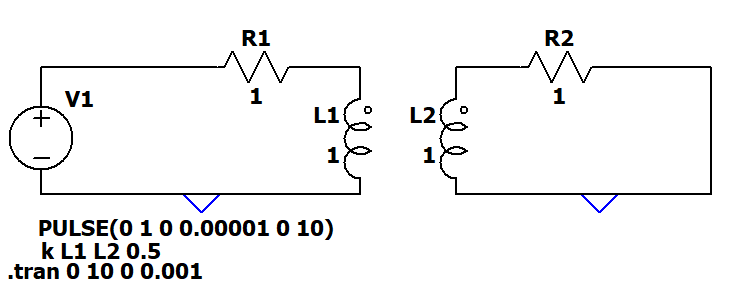

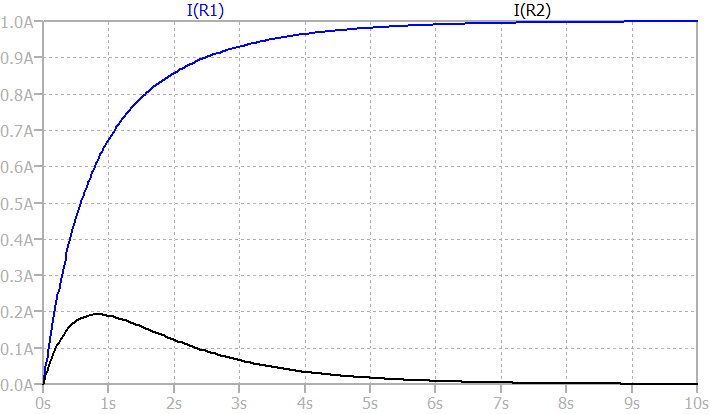

function x = paralelo(n1,n2)

    x = (n1*n2)/(n1+n2);

end